# MATLAB FOR BEGINNERS (Versione Workshop)

## MODULO 1 (BASI)

### 1.1: Default layout e Command Window

*Questa sezione non contiene codice: verrà tutto svolto nella Command Window*

Il layout di default contiene tre pannelli: **Current Folder** (sx), **Command Window** (cx), **Workspace** (dx).

Puoi eseguire comandi scrivendoli nella **Command Window** dopo il simbolo di prompt (>>) e premento il tasto **Invio**. A meno che non venga specificata una variabile di Output, il valore viene salvato in una variabile chiamata Ans. Sono presenti tutte le operazioni standard (+, -, *, /, ^)

Il simbolo (=) in MATLAB è un operatore di *assegnamento*, che assegna l'espressione a destra alla variabile a sinistra. Nota che nella finestra **Workspace** vengono salvate tutte le variabili create, e scrivendo solo il nome della variabile ne verrà mostrato il valore attuale. Puoi chiamare le tue variabili come vuoi, a patto che inizino con una lettera e contengano solo lettere, numeri e underscores (_). Le variabili sono anche Case Sensitive: ad esempio, *Apple* è diverso da *apple*.

Se aggiungi un **punto e virgola** (;) alla fine del comando, il risultato non verrà stampato ma il comando sarà eseguito lo stesso, come puoi vedere nel Workspace. Puoi richiamare comandi scritti in precedenza premendo il tasto Su ↑ sulla tastiera quando il tuo cursore è attivo nella Command Window.

Quando inizi a lavorare su un nuovo problema è buona pratica **ripulire il Workspace**: utilizza il comando *clear all* per eliminare tutte le variabili salvate, e il comando *clc* per pulire la Command Window

### 1.2 Live Editor

Inserire i comandi nella command window è un modo veloce per fare delle prove e vedere i risultati, ma risolvere problemi spesso richiede molte righe di codice e comandi.

Potete salvare le righe di codice e gli output insieme creando un **live script**: clicca in alto su *New Live Script* nella Home Tab per crearne uno.

Il live script è uno strumento molto potente: puoi inserire i comandi nell’**area grigia**, cambiare in **testo** (Text) per aggiungere descrizioni, e cliccare su **run** per eseguire tutto il live script. L’output viene salvato a destra, ma puoi cambiare il layout. Puoi anche dividere il tuo codice in sezioni (*Section Break*), per eseguire solo una porzione di codice per volta con “Run section”. Cliccando sul codice verrà evidenziato l'output corrispondente e viceversa.

Cliccando su *Save* puoi salvare il codice, ouput e testo, sia in formato nativo (*.mlx*) che in pdf. Da ora in avanti useremo il Live Script, e ti incoraggiamo a fare lo stesso quando userai MATLAB in futuro!

Prima di cominciare, scriviamo i tre comandi che resettano l'ambiente. 

- `clc`: pulisce la Command Window

- `clear all: cancella tutte le variabili salvate`

- `close all:` chiude tutte le figure aperte

### 1.3 Costanti e funzioni built-in 

MATLAB contiene alcune **costanti** built-in, come pi per rappresentare *π, *utilizzando il comando *exp(k) *puoi rappresentare e^k.

pi

ans = 3.1416

MATLAB contiene anche un numero pressoché sterminato di funzioni built-in (se hai bisogno di qualcosa, *molto probabilmente* è già stato implementato): eccone alcune matematiche di base

% Seno, coseno, tangente
x = pi / 2;
sin(x)

ans = 1

cos(x)

ans = 6.1232e-17

tan(x)

ans = 1.6331e+16

% Arcoseno, arcocoseno, arcotangente
asin(1)

ans = 1.5708

acos(1)

ans = 0

atan(1)

ans = 0.7854

% Esponenziale, logaritmo in base e, 2, 10
log(exp(1))

ans = 1

log10(10 ^ 4)

ans = 4


% Radice quadrata, valore assoluto
sqrt(4)

ans = 2

% Approssimazione a numeri interi
round(0.1)

ans = 0

round(0.8)

ans = 1

% ceil
ceil(0.3)

ans = 1

% floor
floor(0.8)

ans = 0

% fix
fix(123.3)

ans = 123

% round

Nota che per passare un input alle funzioni vengono utilizzate le parentesi tonde. 

NB: Il nunero immaginario *i* è anch'esso una costante built-in. `cos(pi/2) `e` tan(pi/2) `non hanno restituito i valori attesi, 0 e infinito. Questo è dovuto ad errori di approssimazione nel calcolo coi decimali: esiste un pacchetto apposito per questo tipo di calcoli, chiamato **Symbolic Toolbox**, che vedremo più avanti. 

NB2: È comparso un warning, ma il codice verrà eseguito lo stesso. Cliccando sul triangolino giallo puoi vedere la linea che causa problemi, oltre a suggerimenti utili per ottimizzarlo. Se l'icona è rossa, c'è un errore nel codice e l'esecuzione verrà interrotta.

Solo le prime 4 cifre decimali vengono mostrate nell'output. Se serve più precisione, puoi utilizzare i comandi *format.*

format long

## MODULO 2 (Arrays, Matrici e Indexing)

### 2.1: Creazione di array

*MATLAB* è un'abbreviazione di "matrix laboratory", "laboratorio di matrici". Mentre altri linguaggi di programmazione lavorano principalmente su un numero per volta, MATLAB consente di operare soprattutto su intere matrici e array.

Tutte le variabili di MATLAB sono *array* multidimensionali, indipendentemente dal tipo di dati. Una *matrice* è un array bidimensionale frequentemente utilizzato nell'algebra lineare.

Un numero singolo, chiamato *scalare*, è salvato in MATLAB come un array 1x1, contenente una riga e una colonna.

Puoi creare array con elementi multipli usando le parentesi quadre: separando i numeri con spazi viene creato un vettore **riga **(1xn), separando i numeri col punto e virgola vengono creati vettori **colonna **(nx1)

x = [1 2 3;
     4 5 6;
     7 8 9]

x =      1     2     3
     4     5     6
     7     8     9


Combinando spazi e ; puoi creare una matrice, un array bidimensionale. L'inserimento avviene per righe. Puoi anche fare operazioni all'interno delle parentesi quadre

z = [1 2 3;4 5 6;7 sqrt(2) pi^2]

z =     1.0000    2.0000    3.0000
    4.0000    5.0000    6.0000
    7.0000    1.4142    9.8696


Inserire manualmente i valori può diventare scomodo. Spesso (come vedremo nel modulo 3) sono necessari dei **vettori equispaziati**, come:

-1:1

ans =     -1     0     1


Esistono comandi per creare rapidamente vettori simili, come* l'operatore :*

`partenza:passo:arrivo`

1:5

ans =      1     2     3     4     5


Se invece sai già il numero di elementi che vuoi in un vettore (la sua lunghezza), puoi usare la funzione *linspace*

`linspace(primo el,ultimo el,numero di elementi)`

linspace(1, 500, 13)

ans =     1.0000   42.5833   84.1667  125.7500  167.3333  208.9167  250.5000  292.0833  333.6667  375.2500  416.8333  458.4167  500.0000


Sia : che *linspace* creano vettori riga. Se necessiti di un vettore colonna puoi utilizzare l'operatore apostrofo (*') *per effettuare una trasposizione

linspace(1, 500, 13)'

ans =     1.0000
   42.5833
   84.1667
  125.7500
  167.3333
  208.9167
  250.5000
  292.0833
  333.6667
  375.2500


Esistono molte funzioni per la generazione di array e matrici. Alcune tra le più utili sono `ones,` `zeros, eye `e `rand`:

%% Ricordati di usare help o doc se non sai come usare una funzione!!
% ones
ones(4)

ans =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


% zeros
zeros(3,2)

ans =      0     0
     0     0
     0     0


% eye
eye(4,5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0


% rand
rand(5)

ans =     0.8147    0.0975    0.1576    0.1419    0.6557
    0.9058    0.2785    0.9706    0.4218    0.0357
    0.1270    0.5469    0.9572    0.9157    0.8491
    0.9134    0.9575    0.4854    0.7922    0.9340
    0.6324    0.9649    0.8003    0.9595    0.6787


### 2.2: Indexing

Dato che tutto le variabili in MATLAB sono array, è fondamentale imparare come usarli, come riferirsi a elementi specifici per estrarre o modificare valori: in altre parole, come effettuare l'**indexing**.

La posizione di un valore in un array è chiamata *indice*. Puoi usare l'indice per modificare o estrarre il valore, per esempio, se vuoi il terzo elemento del vettore:

x = 1:10;

NB: in MATLAB, si conta **a partire da 1**

Se vuoi estrarre un elemento da una matrice, basta specificare due indici, uno per riga e uno per colonna. 

A = [1 2 3;4 5 6;7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


È abbastanza comune dover estrarre un intera riga o colonna da una matrice: quando utilizzi due punti (:) al posto dell'indice, significa *prendi tutto*.

Nota che puoi usare la parola *end* come un indice riga o colonna per riferirsi all'ultimo elemento, e puoi anche combinarlo con espressioni aritmetiche.

Puoi anche estrarre **multipli elementi per volta**, usando l'operatore due punti (:) per per specificare il range di valori.

v = linspace(0,10,21)

v =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


### 2.3: Operazioni sui vettori

MATLAB è pensato per lavorare naturalmente su array: la maggiore parte delle operazioni funziona coi vettori

% Aggiungere uno scalare a ogni elemento
x = [5 2 3]

x =      5     2     3



% Sommare due elementi della stessa lunghezza


% Moltiplicare o dividere ciascun elemento per uno scalare, o estrarre


% radice


% Estrarre dati con funzioni statistiche
% max


% sum


% prod


% mean


% sort


L'operatore * consente di effettuare la **moltiplicazione tra matrici**: se vuoi effettuare un prodotto tra vettori di uguale dimensione (tipo prodotto scalare) comparirà un errore.

Per effettuare un prodotto elemeneto per elemento devi utilizzare l'operatore .*

## MODULO 3 (Plotting Data)

In questo modulo utilizzeremo il comando `plot`, il funzionamento di questo comando è vario e dipende dai parametri che gli passeremo come input. Per capirne il funzionamento, ti consigliamo di scrivere nella comandan window `help plot`.

Il comando `help FunctionName` funziona con ogni funzione implementata.

Per avere la documentazione della funzione basterà chiamare il comando `doc FunctionName`

% help

% doc

### 3.1: Plottare vettori

Due vettori della stessa lunghezza possono essere rappresentati uno contro l'altro usando la funzione *plot*.

clc
clear all

mass_m = [75 78 96 74 81 67 59 65 72 82];
height_m = [172 173 169 171 168 180 171 170 170 179];

plot(mass_m, height_m);

Puoi utilizzare input aggiuntivi della funzione plot per specificare colore, tipo di linea, tipo di marker usando simboli differenti tra virgolette. MATLAB suggerisce da solo altri tipi di input che puoi utilizzare, come *LineWidth, MarkerSize* o *MarkerEdgeColor.*

% plotta solo i punti neri 'k' come quadrati 's', con MarkerSize 8


Nota che tutti i plot creano dei nuovi grafici. Se vuoi disegnari i grafici uno sopra l'altro puoi utilizzare il comando *hold on*. Ricordati di utilizzare il comando *hold off* quando hai finito, in modo tale che i grafici successivi non continuino a sovrapporsi.

mass_f = [58 55 68 65 45 59 64 60 61 57];
height_f = [161 160 170 165 158 163 180 175 178 164];

% plotta i valori maschili in nero e quelli femminili in rosso


### 3.2: Plottare funzioni

Per plottare funzioni ci sono diverse opzioni, la prima è usare il comando *plot* creando un vettore di punti denso in corrispondenza dell'intervallo sull'asse x in cui si vuole disegnare il grafico della funzione. Più punti ci sono nel vettore, meglio sarà rappresentato il grafico.

`Crea un vettore x di 100 punti da 0 a 2*pi`

`Con il comando plot(ascisse, ordinate) rappresenta la funzione sin(x) `

Un metodo più comodo per plottare funzioni semplici o ben definite è definire le *anonymous function*, usando le **function handle** in combinazione con la funzione *fplot*. 

`anonymous function = @(lista variabili) espressione`

`utilizza il comando fplot(funzione, [a, b])`

`disegna `$x^3 +3\;x^2$ `(ricorda il .^) da -3 a 3`

%fplot

Vi lasciamo un esempio di plot con altre impostazioni che potrete utilizzare in futuro come template:

f = @(x) x.^3 +20.*x;

retta_tan = @(x) 20.*x;

figure()
fplot(f, 'b-', 'LineWidth', 2)
hold on 
fplot(retta_tan, 'r-', 'LineWidth', 2)
xlim([-5, 5])
ylim([-200, 200])
grid on
title("Funzione y = x^{3}+20x e la sua retta tangente nell'origine")
legend("Funzione y = x^{3}+20x", "Retta tangente")
xlabel('Tempo')
ylabel('Valori')
hold off

L'ultimo metodo è utilizzare il **calcolo simbolico**, come vedremo nel prossimo modulo.

## MODULO 4 (Calcolo simbolico, plot, solve, diff, int, limit)

**Symbolic Math Toolbox** offre funzioni per risolvere, rappresentare e manipolare equazioni di matematica simbolica. Il toolbox offre funzioni per aree comuni della matematica, come il calcolo, l'algebra lineare, le equazioni algebriche e differenziali, la semplificazione e la manipolazione delle equazioni, consentendo di eseguire analiticamente derivazioni, integrazioni, semplificazioni, trasformate e risoluzioni di equazioni. 

È un mondo un po' separato da quello in cui ci siamo mossi finora, in cui definiamo effettivamente delle incognite e **non **variabili informatiche. Ecco alcune applicazioni:

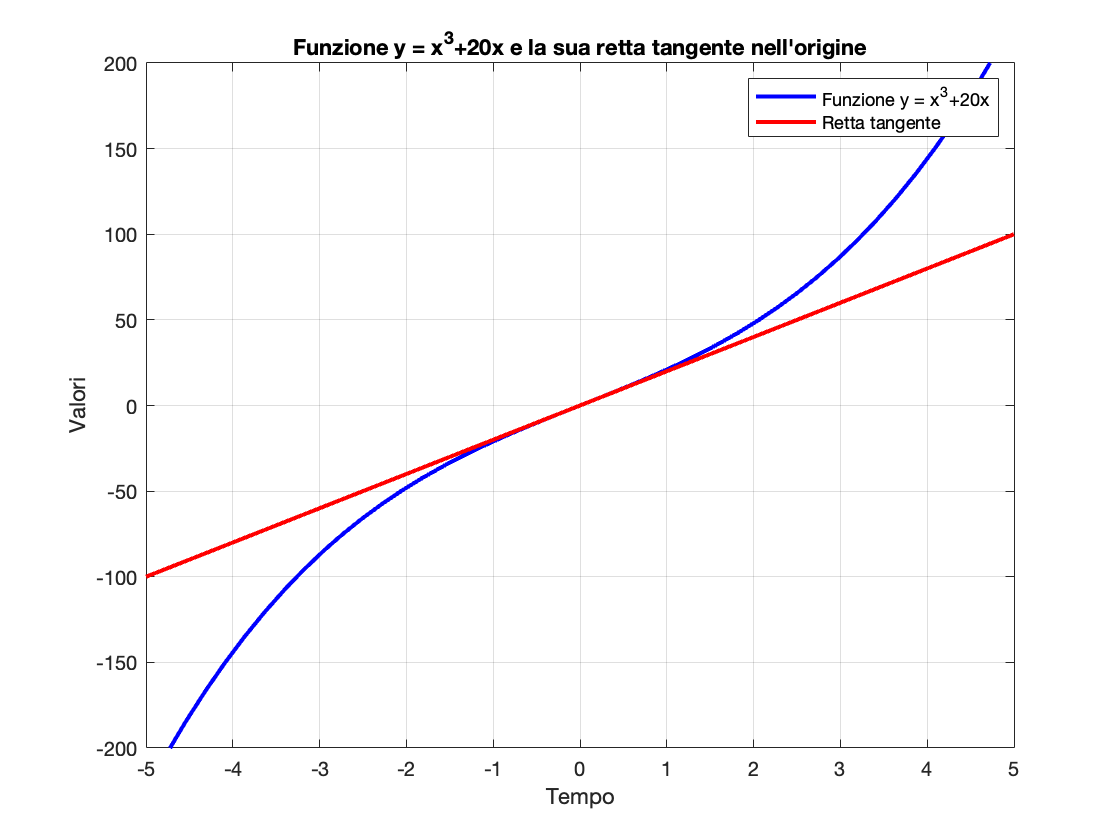

clc
clear all

% syms x y

% Risoluzione di sistemi
% eq1 = x + 2*y == 1
% eq2 = 4*x + 5*y == 5



% Risoluzione di equazioni
eqs = [eq1 eq2]
solve(eqs, [x y])


% Definire funzioni, derivare...
f = (1/(log(x))) * sqrt(x)/(x^2)
df = diff(f, x)

% Compute simplified symbolic expression
simplifiedExpr = simplifyFraction(df)

% ... calcolare sviluppo di Taylor, plottare
g = sin(x)

$$f = \frac{1}{x^{3/2}\,\log\left(x\right)}$$

% taylor

$$df = -\frac{3}{2\,x^{5/2}\,\log\left(x\right)}-\frac{1}{x^{5/2}\,{\log\left(x\right)}^{2}}$$

% ... calcolare integrali...
h(x) = log(x)

$$simplifiedExpr = -\frac{3\,\log\left(x\right)+2}{2\,x^{5/2}\,{\log\left(x\right)}^{2}}$$

h2(x) = 1/(log(x))
% int


% ... calcolare limiti ...
f2 = sin(x)/x
% limit

% ... Plottare superfici in 3D
fsurf(x.^2 + y.^2)

## MODULO 5 (If-else, for, while)

Anche in MATLAB come in tutti i linguaggi di programmazione è possibile utilizzare strutture di controllo quali:` if - else, for, while`.

La sintassi è la seguente:

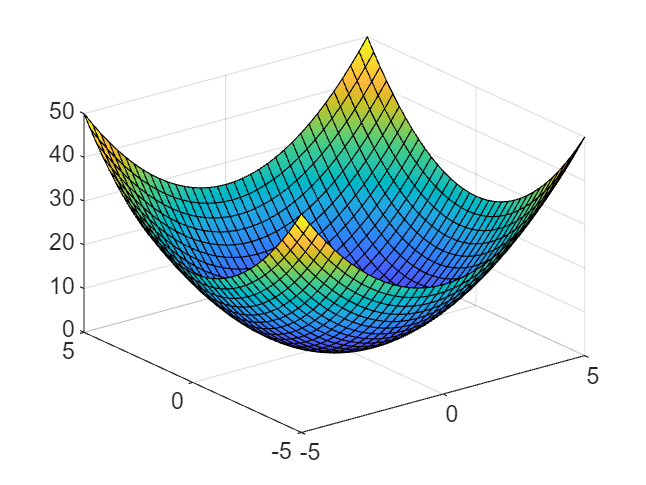

z = randi([-5 5], 1)

% if - else

% for


% while

z = -4

Infine, vi lasciamo con la funzione `tic toc`, che permette di valutare il tempo impiegato per l'esecuzione della sezione di codice contenuto tra le due istruzioni.